% Donald Garcia-Rivas
% Ian Deaton
% Object Recognition Script
% Written for TME 310A Project, Fall 2023, UW Tacoma
% Revision 1, 12/12/2023

% Changes to add: Object identification and characterization (position,
% velocity, acceleration, and possibly size), user interface, optimization.

Currently this script can import a video defined in line 10 of format defined in line 11 and do some movement recognition. Movement because it's more so that the script "sees" motion rather than recognizing that motion as an object. The following steps outline how it works:

- Import video as a VideoReader object

- Convert the video to grayscale to simplify analysis

- Subtract each frame from the one before it, divide by 255, and cast to double

- Check if each pixel exceeded a user-defined threshold for change

- Convert each frame's pixels to either 1 (if changed) or 0 (if not).

- Divide each frame into segments of a size defined by the user in line 25)

- If enough pixels changed in a segment (as defined in line 27) that segment is turned white to highlight the movement.

- The highlighted segments are written into the grayscale video and is output as a video.

I finished this script week before last and have already decided on a few changes. One is to package more tasks into their own function. Also bundle a few of those functions into a class if there are enough related ones. 

The second change might be how to track the movement. My plan was to find the object based on the changed segments but that might be hard since the amount of segments that make up the object isn't consistent from frame to frame which might lead to skips in the objects position. I'd like to find a way to make the object one segment and maybe track just that one segment throughout the frames.

clear all;

inputVideoFileName = "ball_drop"; % Replace with desired video's filename.
inputVideoFileForm = ".mp4"; % Replace with desired video's file format.
inputVideo = VideoReader(inputVideoFileName + inputVideoFileForm);
outputVideo = VideoWriter(inputVideoFileName + "_output", "MPEG-4");
wantTestVideo = 1; % Set to one if a video of raw change detection is desired.
if wantTestVideo == 1
    testVideo = VideoWriter(inputVideoFileName + "_test", "MPEG-4");
end

% These are change detection parameters. pixelChangeThres sets the
% sensitivity to overall changes from one frame to the next. segmentSize
% sets the size of the segments the frames are divided into to look for
% clusters of pixels that have changed to recognize moving objects.
% segmentChangeThres sets the sensitivity to local changes in a segment to
% determine whether a segment contains a moving object or is just noise.
pixelChangeThres = 0.2;
segmentSize = 10;
segmentChangeThres = 0.1;

% This for loop converts the video to grayscale (0-1) and converts into a 
% 3D array to make processing easier. It also crops the video if desired.
disp("Converting to grayscale and cropping");

Converting to grayscale and cropping


for i = 1:inputVideo.NumFrames
    frame = read(inputVideo,i);
    frame = rgb2gray(frame);
    frame = (double(frame)) ./ (255); % Casting to double needed to simplify analysis.
    grayArray(:,:,i) = frame(100:700,975:1100); % This line controls the cropping of the video.
end
disp("Grayscale conversion and cropping complete");

Grayscale conversion and cropping complete



% This for loop does overall change detection by taking each frame and
% subtracting from the previous one to see which pixels changed. It then
% compares it to the pixel change threshold set above and makes each pixel
% either a one or a zero. Another array with these binary frames is made to
% work with later.
disp("Detecting changes");

Detecting changes


if wantTestVideo == 1
    open(testVideo);
end
for i = 1:inputVideo.NumFrames
    if i == 1
        previousFrame = grayArray(:,:,i); %% Potential issue with gray not synced to test. Fix later.
        testArray(:,:,i) = previousFrame;
    else
        currentFrame = grayArray(:,:,i);
        newFrame = abs(previousFrame-currentFrame); % abs() needed to ensure pixels are 0-1.
        newFrame = double(newFrame >= pixelChangeThres);
        testArray(:,:,i) = newFrame;
        writeVideo(testVideo,newFrame);
        previousFrame = currentFrame;
    end
end

if wantTestVideo == 1
    close(testVideo);
end
disp("Change detection complete");

Change detection complete



% This section creates an array with segmentation parameters. segmentsTall
% and Wide are how many segments tall and wide the frames are. If the frame
% isn't evenly divisible, it'll add an extra segment and set extraTall or
% Wide to 1 so that getSegmentLimits can know the last segment is smaller
% than the user defined segment size. Frame information is included next
% and finally the segment change threshold is included for use later.
segmentParameters = [0,0,0,0,segmentSize,size(testArray),segmentChangeThres];
% segmentParameters = [segmentsTall,segmentsWide,extraTall,extraWide,segmentSize,frameHeight,frameWidth,numberOfFrames,segmentChangeThreshold]
% This comment is a legend for segmentParameters.
segmentParameters(1) = fix(segmentParameters(6)/segmentParameters(5));
if mod(segmentParameters(6),segmentParameters(5)) ~= 0
    segmentParameters(3) = 1;
    segmentParameters(1) = segmentParameters(1) + 1;
end
segmentParameters(2) = fix(segmentParameters(7)/segmentParameters(5));
if mod(segmentParameters(7),segmentParameters(5)) ~= 0
    segmentParameters(4) = 1;
    segmentParameters(2) = segmentParameters(2) + 1;
end
disp("Number of segments determined");

Number of segments determined



% This for loop calls the overall analysis function for each frame and
% creates an output array to then write into outputVideo.




% Ian's part 3 code is located here. Creating a global variable to track
% the position of the ball, and updating it in the analyze frame function.
setGlobeC(1);

counter = 1

setGlobeB(zeros(36,2))

ball_loc =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


global counter
global ball_loc

%keeps track of what frame is being referenced throughout function calls
% Each row consists of the ball's x location and y location at said frame;
% e.x. row 7 shows the x and y coordinates for the ball on frame 7



for i = 1:inputVideo.NumFrames
    disp("Analyzing frame " + i + " of " + inputVideo.NumFrames);
    testFrame = testArray(:,:,i);
    referenceFrame = grayArray(:,:,i);
    newFrame = analyzeFrame(testFrame, referenceFrame,segmentParameters);
    outputArray(:,:,i) = newFrame;
    % imshow(newFrame); % For frame by frame inspection.
end

Analyzing frame 1 of 36
Analyzing frame 2 of 36
Analyzing frame 3 of 36
Analyzing frame 4 of 36
Analyzing frame 5 of 36
Analyzing frame 6 of 36
Analyzing frame 7 of 36
Analyzing frame 8 of 36
Analyzing frame 9 of 36
Analyzing frame 10 of 36
Analyzing frame 11 of 36
Analyzing frame 12 of 36
Analyzing frame 13 of 36
Analyzing frame 14 of 36
Analyzing frame 15 of 36
Analyzing frame 16 of 36
Analyzing frame 17 of 36
Analyzing frame 18 of 36
Analyzing frame 19 of 36
Analyzing frame 20 of 36
Analyzing frame 21 of 36
Analyzing frame 22 of 36
Analyzing frame 23 of 36
Analyzing frame 24 of 36
Analyzing frame 25 of 36
Analyzing frame 26 of 36
Analyzing frame 27 of 36
Analyzing frame 28 of 36
Analyzing frame 29 of 36
Analyzing frame 30 of 36
Analyzing frame 31 of 36
Analyzing frame 32 of 36
Analyzing frame 33 of 36
Analyzing frame 34 of 36
Analyzing frame 35 of 36
Analyzing frame 36 of 36



% This for loop creates the output video for the user.
disp("Creating output video");

Creating output video


open(outputVideo);
for i = 6:inputVideo.NumFrames %Starts at 6 to remove junk frames.
    writeVideo(outputVideo,outputArray(:,:,i))
end

close(outputVideo);
disp("Enjoy");

Enjoy


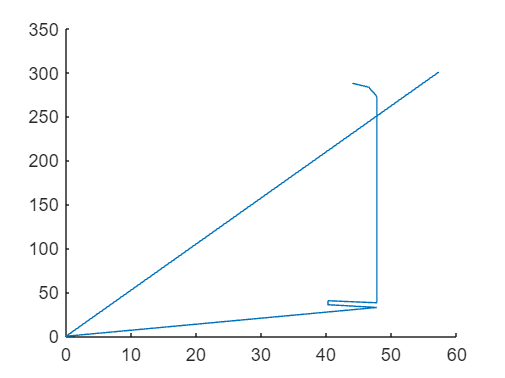



% This code creates the plot of the ball locations for each frame.
hold on
ballxs = zeros(1,36); % formatting in order to plot locations
ballys = zeros(1,36);

for i = 1:36
    ballxs(1,i) = ball_loc(i,1);
    ballys(1,i) = ball_loc(i,2);
end
plot(ballxs,ballys)

% This is the main function which analyzes a frame for motion by segmenting
% the frame and looking a certain change density of the pixels in each
% segment. If that change is met, it replaces that segment with a white box
% to highlight the object. Once this segmentation is complete, a new frame
% with highlights is returned to be written into the output video file.

function [F] = analyzeFrame(testFrame, referenceFrame, segmentParameters)
 
global counter
global ball_loc

  % Code here creates an array to track ball positions, 
  % by taking the segment limits every time a change is detected,
  % and averaging out all of the coordinates to find where the ball
  % "should" be.
  positions = zeros(999,4);
  arbitrary = 1; % encodes where to average points from
  % size is arbitrary; 999 rows chosen to ensure that space doesn't run out



for i = 1:segmentParameters(1)
        for j = 1:segmentParameters(2)
            segmentLimits = getSegmentLimits(i,j,segmentParameters);
            testSegment = getSegment(testFrame,segmentLimits);
            didChange = analyzeSegment(testSegment,segmentParameters(9));
            if didChange
                referenceFrame = changeSegment(referenceFrame, segmentLimits);
              
                % Update ball location
    positions(arbitrary,1) = segmentLimits(1); %top
    positions(arbitrary,2) = segmentLimits(2);%bottom
    positions(arbitrary,3) = segmentLimits(3); %left
    positions(arbitrary,4) = segmentLimits(4); %right

    arbitrary = arbitrary + 1; % each time a change is detected, the position of the ball
    % is recorded by "arbitrary", and then "arbitrary" increments.
    
            end
             

        end
    end
    

    % average out the positions
    yval = 0;
    xval = 0;
  for i = 1:arbitrary %this is where the "arbitrary" variable comes into play
        if i == 1
             yval = (positions(i,1) + positions(i,2))/2;
             xval = (positions(i,3) + positions(i,4))/2;
        else
            yval = (yval + (positions(i,1) + positions(i,2))/2)/2;
            xval = (xval + (positions(i,3) + positions(i,4))/2)/2;
        end

      
      
  end

  ball_loc(counter,1) = xval;
  ball_loc(counter,2) = yval;
  
  counter = counter + 1;
    
    


    F = referenceFrame;
end

% This function gets the pixel array indices associated with a segment of a
% frame.
function [L] = getSegmentLimits(i,j,segmentParameters)
    top = (i-1) * segmentParameters(5) + 1;
    if (segmentParameters(3) == 1) && (i == segmentParameters(1))
        bottom = segmentParameters(6);
    else
        bottom = top + segmentParameters(5) - 1;
    end
    left = (j-1) * segmentParameters(5) + 1;
    if (segmentParameters(4) == 1) && (j == segmentParameters(2))
        right = segmentParameters(7);
    else
        right = left + segmentParameters(5) - 1;
    end
    L = [top,bottom,left,right];
end

% This function returns a segment of pixels from a frame.
function [S] = getSegment(testFrame, segmentLimits)
    S = testFrame(segmentLimits(1):segmentLimits(2),segmentLimits(3):segmentLimits(4));
end

% This function analyzes a segment to check if a user-defined pixel change
% density is met.
function [b] = analyzeSegment(testSegment, segmentChangeThres)
    segmentSize = size(testSegment);
    numberOfChangedPixels = nnz(testSegment);
    numberOfPixels = segmentSize(1) * segmentSize(2);
    changeDensity = numberOfChangedPixels / numberOfPixels;
    b = changeDensity >= segmentChangeThres;
end

% This fucntion replaces a frame segment with a white box. 
function [C] = changeSegment(referenceFrame, segmentLimits)
    for i = segmentLimits(1):segmentLimits(2)
        for j = segmentLimits(3):segmentLimits(4)
            referenceFrame(i,j) = 1;
        end
    end
    C = referenceFrame;
end

function setGlobeC(val)
global counter
counter = val
end

function setGlobeB(val)
global ball_loc
ball_loc = val
end




